clc,clear,close all

### 主程序

clc,clear,close all

% f: 函数
f = @(x) 1./(1+25*x.^2);

% x_train: 插值点
x_train = -1:0.2:1;     %注意，这里 x_train 应该输入一个行向量

% y_train: 插值点处的函数值
y_train = f(x_train);

% x: 要预测的点
x= -1:0.01:1;

% y: 预测的函数值
[y,A] = myfun(x_train,y_train,x);

$$-\frac{390625\,x^{10}}{1768}+\frac{109375\,x^{8}}{221}-\frac{51875\,x^{6}}{136}+\frac{54525\,x^{4}}{442}-\frac{3725\,x^{2}}{221}+1$$


% y_real: 真实的函数值
y_real = f(x);

% interpolation_error: 误差. F 范数
interpolation_error = norm(y_real-y);

% 输出结果
disp('插值拟合结果为')

插值拟合结果为


disp(y)

disp('真实值为')

真实值为


disp(y_real)

  列 1 至 15

    0.0385    0.0392    0.0400    0.0408    0.0416    0.0424    0.0433    0.0442    0.0451    0.0461    0.0471    0.0481    0.0491    0.0502    0.0513

  列 16 至 30

    0.0525    0.0536    0.0549    0.0561    0.0575    0.0588    0.0602    0.0617    0.0632    0.0648    0.0664    0.0681    0.0698    0.0716    0.0735

  列 31 至 45

    0.0755    0.0775    0.0796    0.0818    0.0841    0.0865    0.0890    0.0916    0.0943    0.0971    0.1000    0.1031    0.1063    0.1096    0.1131

  列 46 至 60

    0.1168    0.1206    0.1246    0.1289    0.1333    0.1379    0.1428    0.1479    0.1533    0.1590    0.1649    0.1712    0.1779    0.1848    0.1922

  列 61 至 75

    0.2000    0.2082    0.2169    0.2261    0.2358    0.2462    0.2571    0.2686    0.2809    0.2939    0.3077    0.3223    0.3378    0.3543    0.3717

  列 76 至 90

    0.3902    0.4098    0.4306    0.4525    0.4756    0.5000    0.5256    0.5525    0.5806    0.6098    0.6400    0.6711    0.7030    0.7353    0.7678

  列 91 至 10

disp('误差为')

误差为


disp(interpolation_error)

$$8.2076613364751973841567738674274$$

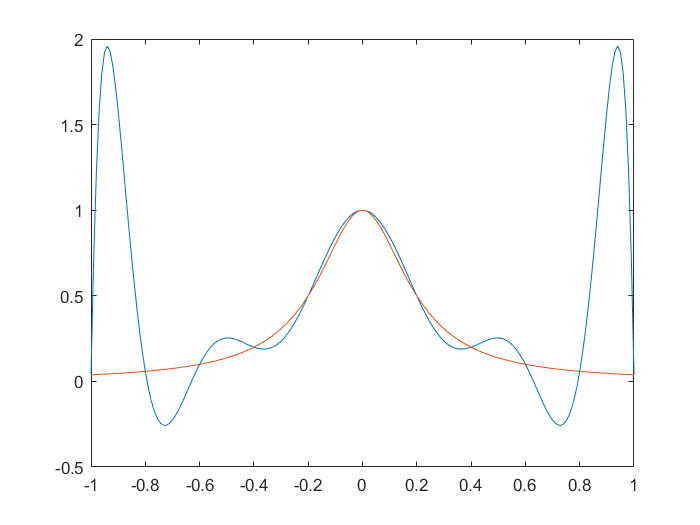

plot(x,y)
hold on
plot(x,y_real)


disp('插值型求积公式的系数为')

插值型求积公式的系数为


disp(A)

    0.0537    0.3551   -0.1621    0.9099   -0.8703    1.4275   -0.8703    0.9099   -0.1621    0.3551    0.0537



disp('插值型求积结果为')

插值型求积结果为


I = sum(f(x_train).*A)

I = 0.9347

disp('真实求积结果为')

真实求积结果为


syms x
f =f(x);
II = double(int(f,x,x_train(1),x_train(end)))

II = 0.5494